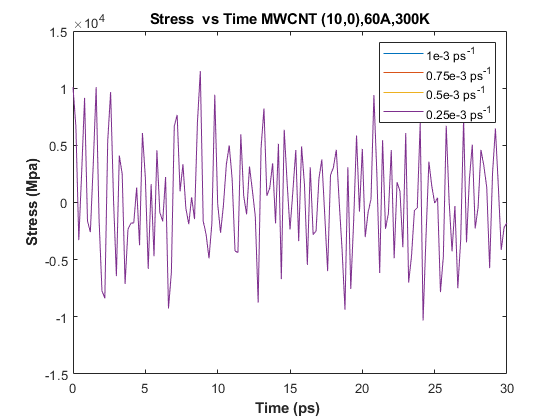

%%%MWCNT
clc
clear all
close all


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.1.
CNT100Equ =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.1.Equi.txt','r');
CNT100Def =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.25.Deform.txt','r');

EquCNT1001 = cell2mat(textscan(CNT100Equ,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ);fclose(CNT100Def);fclose(CNT100Equ75);fclose(CNT100Def75);fclose(CNT100Equ5);
fclose(CNT100Def5);fclose(CNT100Equ25);fclose(CNT100Def25);

figure(1)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5)); hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5)); hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5)); hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5)); hold on
title('Stress  vs Time MWCNT (10,0),60A,300K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
%grid on
hold off


%%%%% make sure upto wichh part linearity follos
f1 = fit(DefCNT1001(1:40,5),DefCNT1001(1:40,6),'poly1') ;     %linear fit
f2 = fit(DefCNT10075(1:40,5),DefCNT10075(1:40,6),'poly1');
f3 = fit(DefCNT1005(1:40,5),DefCNT1005(1:40,6),'poly1');
f4 = fit(DefCNT10025(1:40,5),DefCNT10025(1:40,6),'poly1');
p1= coeffvalues(f1); p2= coeffvalues(f2); p3= coeffvalues(f3); p4= coeffvalues(f4); 
E300K100= [p1(1) p2(1) p3(1) p4(1) ]         %young modulus

E300K100 = 	1.0e+05 *

    4.3799    3.9623    4.2980    4.2974


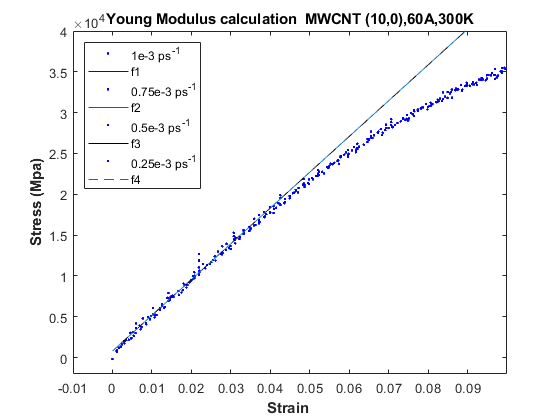


figure(2);   %deformation
plot(f1,'-b',DefCNT1001(:,5),DefCNT1001(:,6)); % strain vs stress
hold on
plot(f1,'-r',DefCNT10075(:,5),DefCNT10075(:,6));
hold on
plot(f1,'-k',DefCNT1005(:,5),DefCNT1005(:,6));
hold on
plot(f1,'--',DefCNT10025(:,5),DefCNT10025(:,6));


title('Young Modulus calculation  MWCNT (10,0),60A,300K')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','f1','0.75e-3 ps^{-1}','f2','0.5e-3 ps^{-1}','f3','0.25e-3 ps^{-1}','f4','Location','northwest')
%grid on
xlim([-0.01 0.1])
ylim([-0.2 4]*1e4)
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young Modulus calculation  MWCNT (10,0),60A,300K.jpg')
 hold off

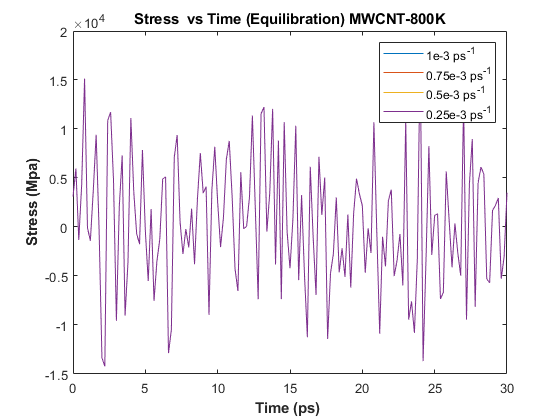



%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.25.Deform.txt','r');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);

figure(3)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5)); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5)); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5)); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5)); 

title('Stress  vs Time (Equilibration) MWCNT-800K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
%grid on
hold off


%%%%% make sure upto wichh part linearity follos
f1 = fit(DefCNT1001(1:24,5),DefCNT1001(1:24,6),'poly1')  ;    %linear fit
f2 = fit(DefCNT10075(1:24,5),DefCNT10075(1:24,6),'poly1');
f3 = fit(DefCNT1005(1:24,5),DefCNT1005(1:24,6),'poly1');
f4 = fit(DefCNT10025(1:24,5),DefCNT10025(1:24,6),'poly1');
p1= coeffvalues(f1); p2= coeffvalues(f2); p3= coeffvalues(f3); p4= coeffvalues(f4); 
E800K100= [p1(1) p2(1) p3(1) p4(1) ]         %young modulus

E800K100 = 	1.0e+05 *

    3.4064    3.7787    3.7382    3.8734


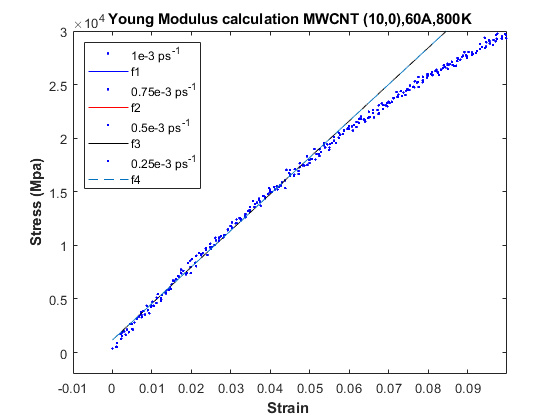


figure(4);   %deformation
plot(f1,'-b',DefCNT1001(:,5),DefCNT1001(:,6)); % strain vs stress
hold on
plot(f1,'-r',DefCNT10075(:,5),DefCNT10075(:,6));
hold on
plot(f1,'-k',DefCNT1005(:,5),DefCNT1005(:,6));
hold on
plot(f1,'--',DefCNT10025(:,5),DefCNT10025(:,6));

title('Young Modulus calculation MWCNT (10,0),60A,800K')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','f1','0.75e-3 ps^{-1}','f2','0.5e-3 ps^{-1}','f3','0.25e-3 ps^{-1}','f4','Location','northwest')
%grid on
xlim([-0.01 0.1])
ylim([-0.2 3]*1e4)
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young Modulus calculation  MWCNT (10,0),60A,800K.jpg')
hold off

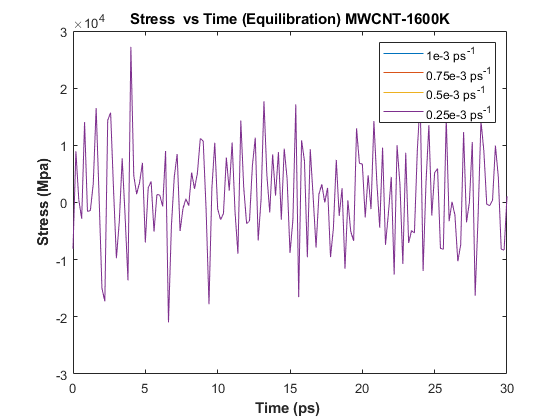


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.25.Deform.txt','r');


EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);

figure(5)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5)); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5)); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5)); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5)); 

title('Stress  vs Time (Equilibration) MWCNT-1600K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
%grid on
hold off


%%%%% make sure upto wichh part linearity follos
f1 = fit(DefCNT1001(1:40,5),DefCNT1001(1:40,6),'poly1') ;     %linear fit
f2 = fit(DefCNT10075(1:40,5),DefCNT10075(1:40,6),'poly1');
f3 = fit(DefCNT1005(1:40,5),DefCNT1005(1:40,6),'poly1');
f4 = fit(DefCNT10025(1:40,5),DefCNT10025(1:40,6),'poly1');
p1= coeffvalues(f1); p2= coeffvalues(f2); p3= coeffvalues(f3); p4= coeffvalues(f4); 
E1600K100= [p1(1) p2(1) p3(1) p4(1) ]         %young modulus

E1600K100 = 	1.0e+05 *

    3.4256    3.2962    3.2176    3.2712


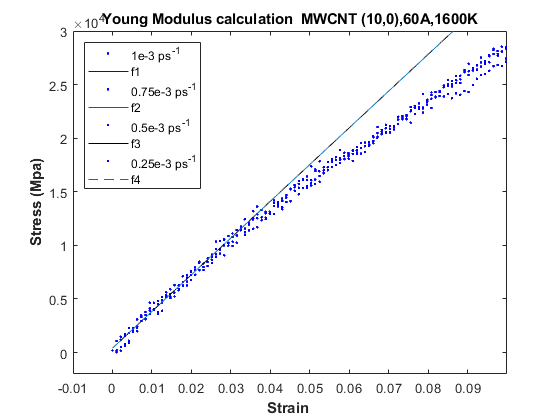


figure(6);   %deformation
plot(f1,'-b',DefCNT1001(:,5),DefCNT1001(:,6)); % strain vs stress
hold on
plot(f1,'-r',DefCNT10075(:,5),DefCNT10075(:,6));
hold on
plot(f1,'-k',DefCNT1005(:,5),DefCNT1005(:,6));
hold on
plot(f1,'--',DefCNT10025(:,5),DefCNT10025(:,6));


title('Young Modulus calculation  MWCNT (10,0),60A,1600K')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','f1','0.75e-3 ps^{-1}','f2','0.5e-3 ps^{-1}','f3','0.25e-3 ps^{-1}','f4','Location','northwest')
%grid on
xlim([-0.01 0.1])
ylim([-0.2 3]*1e4)
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young Modulus calculation  MWCNT (10,0),60A,1600K.jpg')
hold off

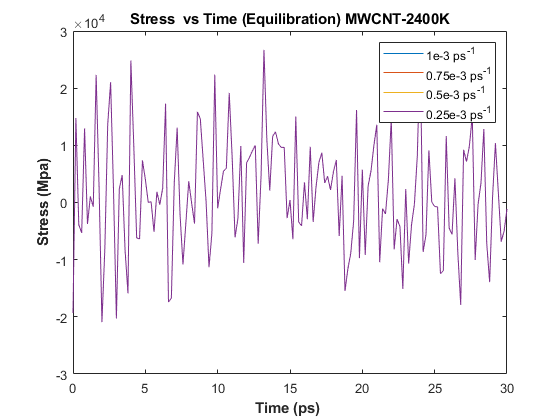

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K

%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.25.Deform.txt','r');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));

fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);


figure(7)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5)); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5)); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5)); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5)); 

title('Stress  vs Time (Equilibration) MWCNT-2400K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
%grid on
hold off


%%%%% make sure upto wichh part linearity follos
f1 = fit(DefCNT1001(1:40,5),DefCNT1001(1:40,6),'poly1')  ;    %linear fit
f2 = fit(DefCNT10075(1:40,5),DefCNT10075(1:40,6),'poly1');
f3 = fit(DefCNT1005(1:40,5),DefCNT1005(1:40,6),'poly1');
f4 = fit(DefCNT10025(1:40,5),DefCNT10025(1:40,6),'poly1');
p1= coeffvalues(f1); p2= coeffvalues(f2); p3= coeffvalues(f3); p4= coeffvalues(f4); 
E2400K100= [p1(1) p2(1) p3(1) p4(1) ]         %young modulus

E2400K100 = 	1.0e+05 *

    3.3603    3.4245    3.3806    3.4030


E100= [E300K100;E800K100;E1600K100;E2400K100]       % young modulus (10,0),300k,800k,....

E100 = 	1.0e+05 *

    4.3799    3.9623    4.2980    4.2974
    3.4064    3.7787    3.7382    3.8734
    3.4256    3.2962    3.2176    3.2712
    3.3603    3.4245    3.3806    3.4030


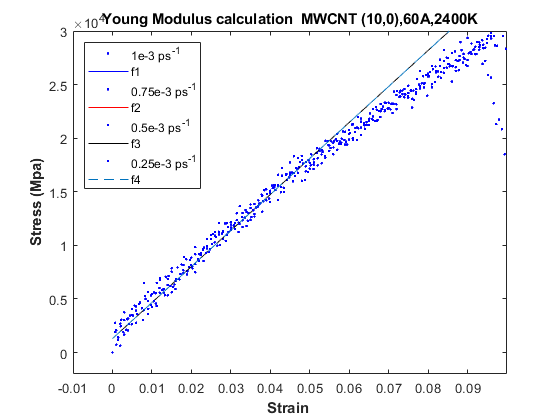

writematrix(E100,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Young_Modulus_MWCNT.txt','Delimiter','tab')


figure(8);   %deformation
plot(f1,'-b',DefCNT1001(:,5),DefCNT1001(:,6)); % strain vs stress
hold on
plot(f1,'-r',DefCNT10075(:,5),DefCNT10075(:,6));
hold on
plot(f1,'-k',DefCNT1005(:,5),DefCNT1005(:,6));
hold on
plot(f1,'--',DefCNT10025(:,5),DefCNT10025(:,6));

title('Young Modulus calculation  MWCNT (10,0),60A,2400K')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','f1','0.75e-3 ps^{-1}','f2','0.5e-3 ps^{-1}','f3','0.25e-3 ps^{-1}','f4','Location','northwest')
%grid on
xlim([-0.01 0.1])
ylim([-0.2 3]*1e4)
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young Modulus calculation  MWCNT (10,0),60A,2400K.jpg')
hold off